# Tarea: Análisis Numérico

## Profesor: Miriam Sosa Díaz

## Ayudante: Andrea Fernanda Rodríguez Rojas

#### Tema: Health-Scientific-Computing. Interpolación

**7.1** — Evaluación de polinomios con la regla de Horner

*(a)* Escriba una rutina que utilice la regla de Horner para evaluar un polinomio p(x) dado su grado n, un array c que contiene sus coeficientes, y el valor t de la variable independiente en que debe ser evaluado.

function p = horner_eval(c, t)
% Evalúa el polinomio con coeficientes c en el punto t
% c(1) es el coeficiente de mayor grado, c(end) el término independiente
    n = length(c);
    p = c(1);
    for k = 2:n
        p = p * t + c(k);
    end
end

% Prueba 7.1 (a)
% p(x) = 2x^3 - x^2 + 3x - 5  evaluado en t = 3
c = [2, -1, 3, -5];
t = 3;
resultado = horner_eval(c, t);
fprintf('p(%g) = %g\n', t, resultado)

p(3) = 49


% Verificación directa: 2(27) - 9 + 9 - 5 = 49

**7.1** *(b)* Agregue opciones para evaluar la derivada p'(t) o la integral de p(t) entre a y b.

function dp = horner_derivada(c, t)
% Evalúa la derivada p'(t) usando la regla de Horner
% Los coeficientes de p'(x) se obtienen derivando term a term
    n = length(c);
    % Coeficientes de la derivada
    dc = zeros(1, n-1);
    for k = 1:n-1
        dc(k) = c(k) * (n - k);
    end
    dp = horner_eval(dc, t);
end

function I = horner_integral(c, a, b)
% Evalúa la integral definida de p(t) entre a y b usando Horner
% Los coeficientes de la primitiva se obtienen integrando term a term
    n = length(c);
    % Coeficientes de la primitiva
    ic = zeros(1, n+1);
    for k = 1:n
        ic(k) = c(k) / (n - k + 1);
    end
    % ic(n+1) = 0 constante de integración
    I = horner_eval(ic, b) - horner_eval(ic, a);
end

% Prueba 7.1 (b)
% p(x) = 2x^3 - x^2 + 3x - 5
c = [2, -1, 3, -5];
t = 3;
a = 0;
b = 3;

dp = horner_derivada(c, t);
I  = horner_integral(c, a, b);

fprintf('p(%g)        = %g\n', t, horner_eval(c, t))

p(3)        = 49


fprintf('p''(%g)       = %g\n', t, dp)

p'(3)       = 51


fprintf('integral     = %g\n', I)

integral     = 30


**7.2** — Interpolante polinomial de Newton

*(a)* Escriba una rutina para calcular el interpolante polinomial de Newton para un conjunto dado de puntos de datos, y una segunda rutina para evaluar el interpolante de Newton en un valor de argumento dado utilizando la regla de Horner.

function c = newton_coeficientes(x, y)
% Calcula los coeficientes de diferencias divididas de Newton
    n = length(x);
    D = zeros(n, n);
    D(:,1) = y(:);
    for j = 2:n
        for i = j:n
            D(i,j) = (D(i,j-1) - D(i-1,j-1)) / (x(i) - x(i-j+1));
        end
    end
    c = diag(D)';
end

function p = horner_newton(c, x, t)
% Evalúa el interpolante de Newton en t usando la regla de Horner
    n = length(c);
    p = c(n);
    for k = n-1:-1:1
        p = p * (t - x(k)) + c(k);
    end
end

% Prueba 7.2 (a)
x = [-2, -1, 0, 1, 2];
y = 1 ./ (1 + x.^2);

c = newton_coeficientes(x, y);

fprintf('Coeficientes de Newton:\n')

Coeficientes de Newton:


for k = 1:length(c)
    fprintf('  c(%d) = %10.6f\n', k, c(k))
end

  c(1) =   0.200000
  c(2) =   0.300000
  c(3) =   0.100000
  c(4) =  -0.200000
  c(5) =   0.100000



x_test = 0.5;
p_test = horner_newton(c, x, x_test);
fprintf('\nEvaluación en x = %.2f:\n', x_test)


Evaluación en x = 0.50:


fprintf('  P(%.2f)  = %.8f\n', x_test, p_test)

  P(0.50)  = 0.85625000


fprintf('  f(%.2f)  = %.8f\n', x_test, 1/(1+x_test^2))

  f(0.50)  = 0.80000000


fprintf('  Error    = %.2e\n',  abs(p_test - 1/(1+x_test^2)))

  Error    = 5.62e-02


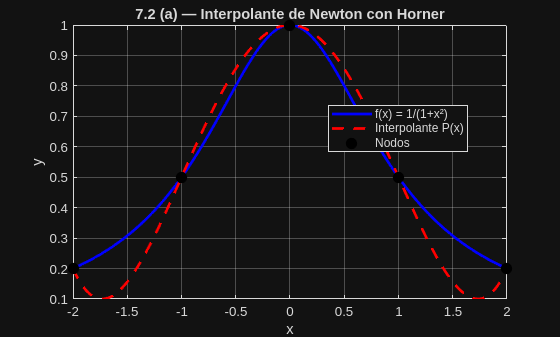


% Grafica
x_suave = linspace(-2, 2, 200);
p_suave = arrayfun(@(t) horner_newton(c, x, t), x_suave);
f_real  = 1 ./ (1 + x_suave.^2);

figure(1); clf;
plot(x_suave, f_real,  'b-',  'LineWidth', 2, 'DisplayName', 'f(x) = 1/(1+x²)')
hold on
plot(x_suave, p_suave, 'r--', 'LineWidth', 2, 'DisplayName', 'Interpolante P(x)')
plot(x, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Nodos')
xlabel('x'); ylabel('y')
title('7.2 (a) — Interpolante de Newton con Horner')
legend('Location', 'best'); grid on

**7.2** *(b)* Escriba una rutina para calcular el nuevo interpolante polinomial de Newton cuando se agrega un nuevo punto de datos.

function [c_new, x_out] = newton_agregar_punto(c, x, x_new, y_new)
% Agrega un nuevo punto al interpolante de Newton sin recalcular desde cero
    p_new     = horner_newton(c, x, x_new);
    prod_denom = prod(x_new - x);
    c_extra   = (y_new - p_new) / prod_denom;
    c_new     = [c, c_extra];
    x_out     = [x, x_new];
end

% Prueba 7.2 (b)
x_nuevo = 1.5;
y_nuevo = 1 / (1 + x_nuevo^2);

[c_amp, x_amp] = newton_agregar_punto(c, x, x_nuevo, y_nuevo);

% Verificación contra recálculo completo
x_full = [x, x_nuevo];
y_full = [y, y_nuevo];
c_full = newton_coeficientes(x_full, y_full);

fprintf('Verificación incremental vs completo:\n')

Verificación incremental vs completo:


fprintf('  %-6s %-18s %-18s %-12s\n', 'Coef.', 'Incremental', 'Completo', 'Diferencia')

  Coef.  Incremental        Completo           Diferencia  


for k = 1:length(c_amp)
    fprintf('  c(%-2d)  %16.10f  %16.10f  %.2e\n', ...
        k, c_amp(k), c_full(k), abs(c_amp(k)-c_full(k)))
end

  c(1 )      0.2000000000      0.2000000000  0.00e+00
  c(2 )      0.3000000000      0.3000000000  0.00e+00
  c(3 )      0.1000000000      0.1000000000  0.00e+00
  c(4 )     -0.2000000000     -0.2000000000  0.00e+00
  c(5 )      0.1000000000      0.1000000000  0.00e+00
  c(6 )     -0.0461538462     -0.0461538462  4.16e-17


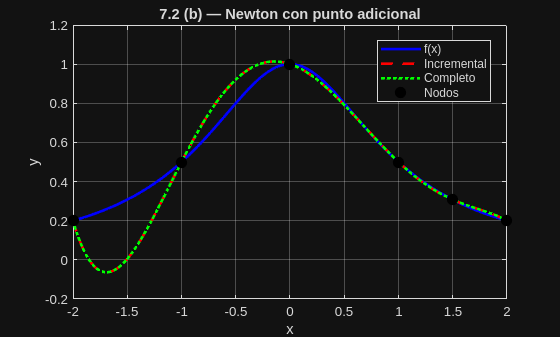


% Grafica
x_suave = linspace(-2, 2, 200);
p_amp   = arrayfun(@(t) horner_newton(c_amp,  x_amp,  t), x_suave);
p_full  = arrayfun(@(t) horner_newton(c_full, x_full, t), x_suave);
f_real  = 1 ./ (1 + x_suave.^2);

figure(2); clf;
plot(x_suave, f_real,  'b-',  'LineWidth', 2, 'DisplayName', 'f(x)')
hold on
plot(x_suave, p_amp,   'r--', 'LineWidth', 2, 'DisplayName', 'Incremental')
plot(x_suave, p_full,  'g:',  'LineWidth', 2, 'DisplayName', 'Completo')
plot(x_amp, y_full, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Nodos')
xlabel('x'); ylabel('y')
title('7.2 (b) — Newton con punto adicional')
legend('Location', 'best'); grid on

**7.2** *(c)* Escriba una rutina recursiva que implemente la parte (a) llamando a la rutina de la parte (b) recursivamente. Compare su rendimiento con la implementación original.

function c = newton_recursivo(x, y)
% Construye el interpolante de Newton de forma recursiva
    n = length(x);
    if n == 1
        c = y(1);
    else
        c_prev = newton_recursivo(x(1:n-1), y(1:n-1));
        [c, ~] = newton_agregar_punto(c_prev, x(1:n-1), x(n), y(n));
    end
end

% Prueba 7.2 (c) — correctitud
c_rec = newton_recursivo(x, y);

fprintf('Recursivo vs iterativo:\n')

Recursivo vs iterativo:


fprintf('  %-6s %-18s %-18s %-12s\n', 'Coef.', 'Recursivo', 'Iterativo', 'Diferencia')

  Coef.  Recursivo          Iterativo          Diferencia  


for k = 1:length(c)
    fprintf('  c(%-2d)  %16.10f  %16.10f  %.2e\n', ...
        k, c_rec(k), c(k), abs(c_rec(k)-c(k)))
end

  c(1 )      0.2000000000      0.2000000000  0.00e+00
  c(2 )      0.3000000000      0.3000000000  0.00e+00
  c(3 )      0.1000000000      0.1000000000  2.78e-17
  c(4 )     -0.2000000000     -0.2000000000  2.78e-17
  c(5 )      0.1000000000      0.1000000000  1.39e-17



% Comparación de rendimiento
n_puntos = 5:5:50;
t_iter   = zeros(size(n_puntos));
t_rec    = zeros(size(n_puntos));
n_rep    = 100;

for idx = 1:length(n_puntos)
    n  = n_puntos(idx);
    xi = linspace(-2, 2, n);
    yi = 1 ./ (1 + xi.^2);

    t0 = tic;
    for r = 1:n_rep
        newton_coeficientes(xi, yi);
    end
    t_iter(idx) = toc(t0) / n_rep;

    t0 = tic;
    for r = 1:n_rep
        newton_recursivo(xi, yi);
    end
    t_rec(idx) = toc(t0) / n_rep;
end

fprintf('\nRendimiento (promedio %d repeticiones):\n', n_rep)


Rendimiento (promedio 100 repeticiones):


fprintf('  %-6s %-16s %-16s %-10s\n', 'n', 'Iterativo(s)', 'Recursivo(s)', 'Ratio')

  n      Iterativo(s)     Recursivo(s)     Ratio     


for idx = 1:length(n_puntos)
    fprintf('  %-6d %-16.6e %-16.6e %-10.2f\n', ...
        n_puntos(idx), t_iter(idx), t_rec(idx), t_rec(idx)/t_iter(idx))
end

  5      4.809000e-05     6.486000e-05     1.35      
  10     3.120000e-06     1.266000e-05     4.06      
  15     8.800000e-06     2.015000e-05     2.29      
  20     9.370000e-06     3.124000e-05     3.33      
  25     1.437000e-05     5.145000e-05     3.58      
  30     1.567000e-05     3.896000e-05     2.49      
  35     1.538000e-05     1.337500e-04     8.70      
  40     6.727000e-05     1.145700e-04     1.70      
  45     2.631000e-05     9.422000e-05     3.58      
  50     3.103000e-05     8.812000e-05     2.84      


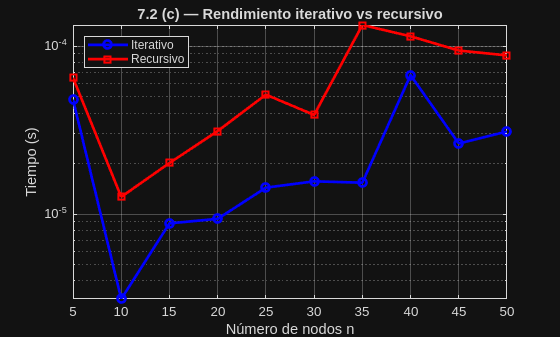


figure(3); clf;
semilogy(n_puntos, t_iter, 'b-o', 'LineWidth', 2, 'DisplayName', 'Iterativo')
hold on
semilogy(n_puntos, t_rec,  'r-s', 'LineWidth', 2, 'DisplayName', 'Recursivo')
xlabel('Número de nodos n'); ylabel('Tiempo (s)')
title('7.2 (c) — Rendimiento iterativo vs recursivo')
legend('Location', 'northwest'); grid on

**7.3** — Interpolación con splines cúbicos

*(a)* El sistema de ecuaciones del Ejemplo 7.6 en forma matricial es.     % Lo escribi en librerta

**7.3** *(b)* Resolver el sistema 8x8 con los datos del Ejemplo 7.1

Tres puntos de datos: (-2, -27), (0, -1), (1, 0)

% Datos del Ejemplo 7.1
t1 = -2;  t2 = 0;  t3 = 1;
y1 = -27; y2 = -1; y3 = 0;

% Matriz A del sistema 8x8
A = [
    1,  t1,  t1^2,  t1^3,  0,   0,    0,      0;
    1,  t2,  t2^2,  t2^3,  0,   0,    0,      0;
    0,   0,     0,     0,  1,  t2,  t2^2,  t2^3;
    0,   0,     0,     0,  1,  t3,  t3^2,  t3^3;
    0,   1,  2*t2, 3*t2^2, 0,  -1, -2*t2, -3*t2^2;
    0,   0,     2,   6*t2, 0,   0,    -2,   -6*t2;
    0,   0,     2,   6*t1, 0,   0,     0,       0;
    0,   0,     0,      0, 0,   0,     2,    6*t3
];

b = [y1; y2; y2; y3; 0; 0; 0; 0];

coef = A \ b;

fprintf('Coeficientes del spline:\n')

Coeficientes del spline:


fprintf('  alpha1 = %10.6f\n', coef(1))

  alpha1 =  -1.000000


fprintf('  alpha2 = %10.6f\n', coef(2))

  alpha2 =   5.000000


fprintf('  alpha3 = %10.6f\n', coef(3))

  alpha3 =  -6.000000


fprintf('  alpha4 = %10.6f\n', coef(4))

  alpha4 =  -1.000000


fprintf('  beta1  = %10.6f\n', coef(5))

  beta1  =  -1.000000


fprintf('  beta2  = %10.6f\n', coef(6))

  beta2  =   5.000000


fprintf('  beta3  = %10.6f\n', coef(7))

  beta3  =  -6.000000


fprintf('  beta4  = %10.6f\n', coef(8))

  beta4  =   2.000000


**7.3** *(c)* Graficar la spline cúbica natural, sus derivadas y verificar condiciones

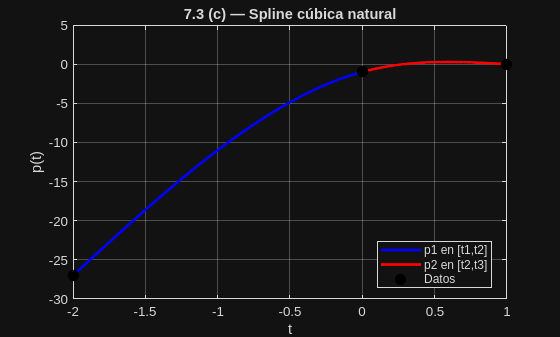

% Extraer coeficientes
a1=coef(1); a2=coef(2); a3=coef(3); a4=coef(4);
b1=coef(5); b2=coef(6); b3=coef(7); b4=coef(8);

t_izq = linspace(t1, t2, 200);
t_der = linspace(t2, t3, 200);

p1   = a1 + a2*t_izq + a3*t_izq.^2 + a4*t_izq.^3;
p2   = b1 + b2*t_der + b3*t_der.^2 + b4*t_der.^3;
dp1  = a2 + 2*a3*t_izq + 3*a4*t_izq.^2;
dp2  = b2 + 2*b3*t_der + 3*b4*t_der.^2;
d2p1 = 2*a3 + 6*a4*t_izq;
d2p2 = 2*b3 + 6*b4*t_der;

figure(4); clf;
plot(t_izq, p1, 'b-', 'LineWidth', 2, 'DisplayName', 'p1 en [t1,t2]')
hold on
plot(t_der, p2, 'r-', 'LineWidth', 2, 'DisplayName', 'p2 en [t2,t3]')
plot([t1 t2 t3], [y1 y2 y3], 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Datos')
xlabel('t'); ylabel('p(t)')
title('7.3 (c) — Spline cúbica natural')
legend('Location', 'best'); grid on

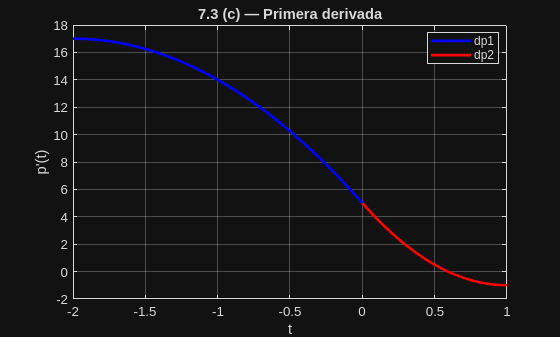


figure(5); clf;
plot(t_izq, dp1, 'b-', 'LineWidth', 2, 'DisplayName', 'dp1')
hold on
plot(t_der, dp2, 'r-', 'LineWidth', 2, 'DisplayName', 'dp2')
xlabel('t'); ylabel('p''(t)')
title('7.3 (c) — Primera derivada')
legend('Location', 'best'); grid on

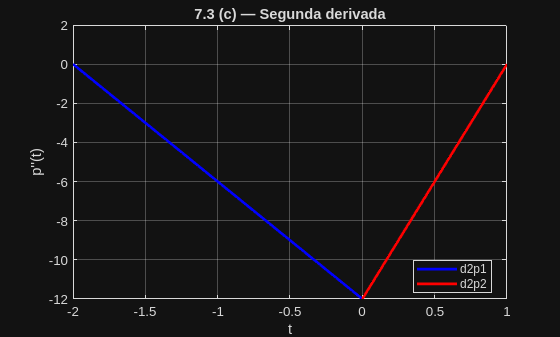


figure(6); clf;
plot(t_izq, d2p1, 'b-', 'LineWidth', 2, 'DisplayName', 'd2p1')
hold on
plot(t_der, d2p2, 'r-', 'LineWidth', 2, 'DisplayName', 'd2p2')
xlabel('t'); ylabel('p''''(t)')
title('7.3 (c) — Segunda derivada')
legend('Location', 'best'); grid on

% Verificación numérica de condiciones
fprintf('--- Verificación de condiciones ---\n\n')

--- Verificación de condiciones ---



fprintf('Interpolación:\n')

Interpolación:


fprintf('  p1(t1) = %8.4f  (debe ser y1 = %8.4f)\n', a1+a2*t1+a3*t1^2+a4*t1^3, y1)

  p1(t1) = -27.0000  (debe ser y1 = -27.0000)


fprintf('  p1(t2) = %8.4f  (debe ser y2 = %8.4f)\n', a1+a2*t2+a3*t2^2+a4*t2^3, y2)

  p1(t2) =  -1.0000  (debe ser y2 =  -1.0000)


fprintf('  p2(t2) = %8.4f  (debe ser y2 = %8.4f)\n', b1+b2*t2+b3*t2^2+b4*t2^3, y2)

  p2(t2) =  -1.0000  (debe ser y2 =  -1.0000)


fprintf('  p2(t3) = %8.4f  (debe ser y3 = %8.4f)\n', b1+b2*t3+b3*t3^2+b4*t3^3, y3)

  p2(t3) =  -0.0000  (debe ser y3 =   0.0000)


fprintf('\nContinuidad primera derivada en t2:\n')


Continuidad primera derivada en t2:


fprintf('  dp1(t2) = %8.4f\n', a2+2*a3*t2+3*a4*t2^2)

  dp1(t2) =   5.0000


fprintf('  dp2(t2) = %8.4f\n', b2+2*b3*t2+3*b4*t2^2)

  dp2(t2) =   5.0000


fprintf('\nContinuidad segunda derivada en t2:\n')


Continuidad segunda derivada en t2:


fprintf('  d2p1(t2) = %8.4f\n', 2*a3+6*a4*t2)

  d2p1(t2) = -12.0000


fprintf('  d2p2(t2) = %8.4f\n', 2*b3+6*b4*t2)

  d2p2(t2) = -12.0000


fprintf('\nCondiciones naturales:\n')


Condiciones naturales:


fprintf('  d2p1(t1) = %8.4f  (debe ser 0)\n', 2*a3+6*a4*t1)

  d2p1(t1) =   0.0000  (debe ser 0)


fprintf('  d2p2(t3) = %8.4f  (debe ser 0)\n', 2*b3+6*b4*t3)

  d2p2(t3) =   0.0000  (debe ser 0)


**7.4** — Interpolación de datos experimentales

| t | 0.0 | 0.5 | 1.0 | 6.0 | 7.0 | 9.0 |

| y | 0.0 | 1.6 | 2.0 | 2.0 | 1.5 | 0.0 |

*(a)* Determine el polinomio de grado cinco que interpola los datos 

y grafíquelo en [0, 9].

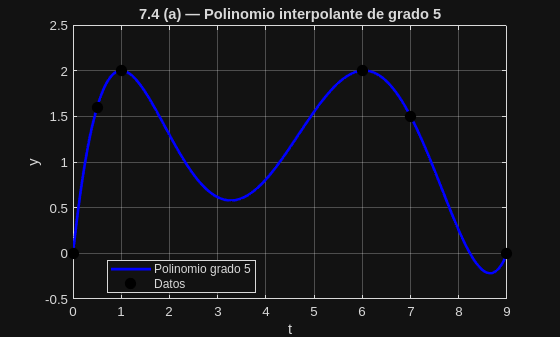

% Datos
t = [0.0, 0.5, 1.0, 6.0, 7.0, 9.0];
y = [0.0, 1.6, 2.0, 2.0, 1.5, 0.0];

% Polinomio grado 5
p = polyfit(t, y, 5);
t_suave = linspace(0, 9, 500);
y_poly  = polyval(p, t_suave);

figure(7); clf;
plot(t_suave, y_poly, 'b-', 'LineWidth', 2, 'DisplayName', 'Polinomio grado 5')
hold on
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Datos')
xlabel('t'); ylabel('y')
title('7.4 (a) — Polinomio interpolante de grado 5')
legend('Location', 'best'); grid on

**7.4** *(b)* Determine una spline cúbica que interpole los datos y grafíquela en el mismo rango.

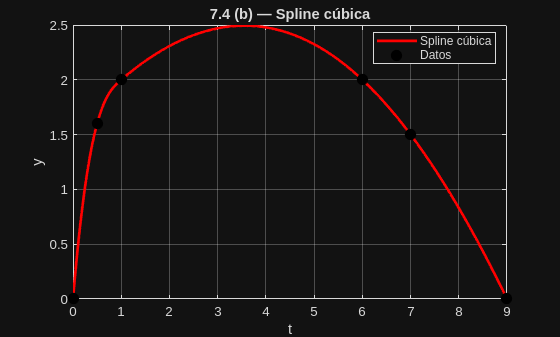

y_spline = spline(t, y, t_suave);

figure(8); clf;
plot(t_suave, y_spline, 'r-', 'LineWidth', 2, 'DisplayName', 'Spline cúbica')
hold on
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Datos')
xlabel('t'); ylabel('y')
title('7.4 (b) — Spline cúbica')
legend('Location', 'best'); grid on

**7.4** *(c)* — ¿Qué interpolador da valores más razonables?

La spline cúbica da valores más razonables entre los puntos de datos. El polinomio de grado 5 presenta oscilaciones pronunciadas fuera del comportamiento esperado, especialmente en los extremos — fenómeno de Runge. Los primeros tres puntos están muy juntos (t = 0, 0.5, 1.0) y los últimos más separados (t = 6, 7, 9), lo que agrava el problema. La spline cúbica evita esto ajustando polinomios locales en cada subintervalo.

**7.4** *(d)* — ¿Sería mejor la interpolación lineal por tramos?

Para estos datos la interpolación lineal podría ser razonable ya que los datos no sugieren un comportamiento altamente curvo entre puntos. Sin embargo produce una curva con esquinas en cada nodo, sin derivada continua, lo que puede no ser adecuado si se busca una curva físicamente realista. La spline cúbica ofrece el mejor balance: es suave, local y no oscila. La interpolación lineal sería preferible solo si se desconfía del comportamiento de la spline en el intervalo [1.0, 6.0] donde no hay ningún dato en 5 unidades de distancia.

**7.5** — Aproximación a la función raíz cuadrada

| t | 0 | 1 | 4 | 9 | 16 | 25 | 36 | 49 | 64 |

| y | 0 | 1 | 2 | 3 |  4 |  5 |  6 |  7 |  8 |

*(a)* Calcule el polinomio de grado ocho que interpola estos nueve puntos y grafíquelo junto con sqrt(t) en [0, 64].

% Datos
t = [0, 1, 4, 9, 16, 25, 36, 49, 64];
y = [0, 1, 2, 3,  4,  5,  6,  7,  8];

% Polinomio grado 8
p = polyfit(t, y, 8);

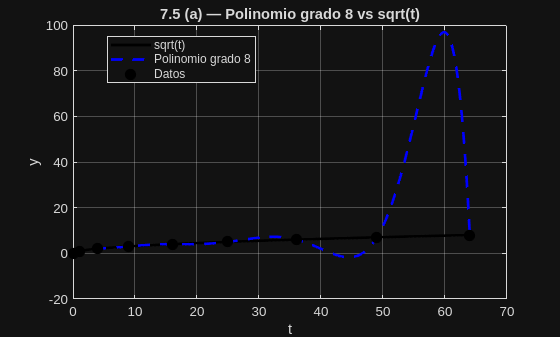

t_suave = linspace(0, 64, 500);
y_poly  = polyval(p, t_suave);
y_sqrt  = sqrt(t_suave);

figure(9); clf;
plot(t_suave, y_sqrt,  'k-',  'LineWidth', 2, 'DisplayName', 'sqrt(t)')
hold on
plot(t_suave, y_poly,  'b--', 'LineWidth', 2, 'DisplayName', 'Polinomio grado 8')
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Datos')
xlabel('t'); ylabel('y')
title('7.5 (a) — Polinomio grado 8 vs sqrt(t)')
legend('Location', 'best'); grid on

**7.5** *(b)* Utilice una rutina de spline cúbico para interpolar los mismos datos y grafíquela junto con sqrt(t).

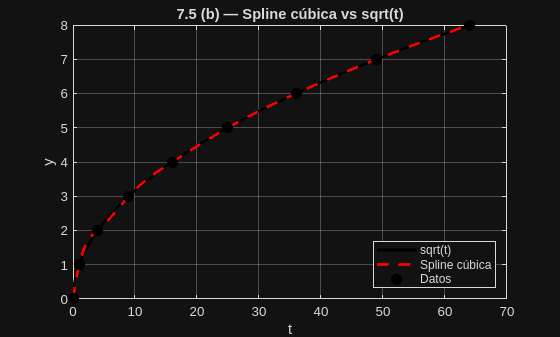

y_spline = spline(t, y, t_suave);

figure(10); clf;
plot(t_suave, y_sqrt,   'k-',  'LineWidth', 2, 'DisplayName', 'sqrt(t)')
hold on
plot(t_suave, y_spline, 'r--', 'LineWidth', 2, 'DisplayName', 'Spline cúbica')
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Datos')
xlabel('t'); ylabel('y')
title('7.5 (b) — Spline cúbica vs sqrt(t)')
legend('Location', 'best'); grid on

**7.5** *(c)* — ¿Cuál interpolante es más preciso en la mayor parte del dominio?

La spline cúbica es más precisa en la mayor parte del dominio [0, 64]. Se adapta bien a la forma suave y creciente de sqrt(t) manteniéndose muy cerca de la función real en casi todo el rango. El polinomio de grado 8 presenta oscilaciones que lo alejan de sqrt(t) especialmente hacia los extremos.

**7.5** *(d)* — ¿Cuál interpolante es más preciso entre 0 y 1?

En [0, 1] el polinomio de grado 8 puede comportarse mejor que la spline cúbica. sqrt(t) tiene derivada infinita en t = 0, la curva es verticalmente muy pronunciada cerca del origen. La spline impone condiciones de suavidad que no puede satisfacer bien ante ese comportamiento singular, resultando en una mala aproximación en ese subintervalo. El polinomio global al usar información de todos los nodos puede capturar ese comportamiento de forma más aproximada.

**7.6** — Aproximación a la función gamma

La función gamma está definida por:

Γ(x) = ∫₀^∞ t^(x-1) e^(-t) dt,  x > 0

Para argumento entero n: Γ(n) = (n-1)!

| t | 1 | 2 | 3 | 4 |  5 |

| y | 1 | 1 | 2 | 6 | 24 |

*(a)* Calcule el polinomio de grado cuatro que interpola estos cinco puntos y grafíquelo junto con gamma(t) en [1, 5].

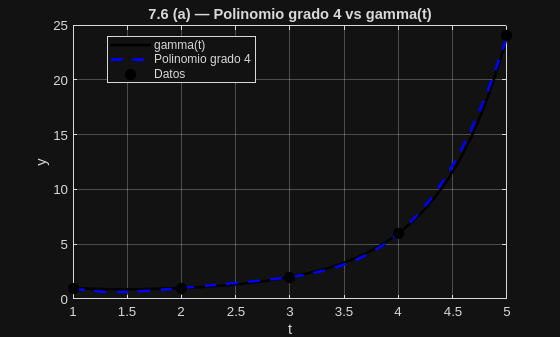

% Datos
t = [1, 2, 3, 4,  5];
y = [1, 1, 2, 6, 24];

% Polinomio grado 4
p = polyfit(t, y, 4);
t_suave = linspace(1, 5, 500);
y_poly  = polyval(p, t_suave);
y_gamma = gamma(t_suave);

figure(11); clf;
plot(t_suave, y_gamma, 'k-',  'LineWidth', 2, 'DisplayName', 'gamma(t)')
hold on
plot(t_suave, y_poly,  'b--', 'LineWidth', 2, 'DisplayName', 'Polinomio grado 4')
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Datos')
xlabel('t'); ylabel('y')
title('7.6 (a) — Polinomio grado 4 vs gamma(t)')
legend('Location', 'best'); grid on

**7.6** *(b)* Utilice una rutina de spline cúbico para interpolar los mismos datos y grafíquela junto con gamma(t).

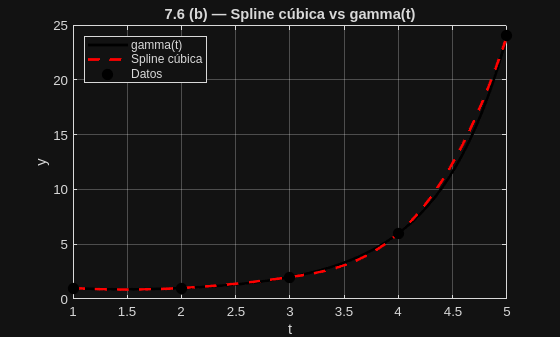

y_spline = spline(t, y, t_suave);

figure(12); clf;
plot(t_suave, y_gamma,  'k-',  'LineWidth', 2, 'DisplayName', 'gamma(t)')
hold on
plot(t_suave, y_spline, 'r--', 'LineWidth', 2, 'DisplayName', 'Spline cúbica')
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Datos')
xlabel('t'); ylabel('y')
title('7.6 (b) — Spline cúbica vs gamma(t)')
legend('Location', 'best'); grid on

**7.6** *(c)* — ¿Cuál interpolante es más preciso en la mayor parte del dominio?

La spline cúbica es más precisa en la mayor parte del dominio [1, 5]. La función gamma crece muy rápido hacia t = 5 y el polinomio de grado 4 no logra capturar ese crecimiento acelerado al final del intervalo, produciéndose una curva que se aleja notablemente de gamma(t) cerca de t = 5. La spline al trabajar localmente se ajusta mejor a ese crecimiento en cada subintervalo.

**7.6** *(d)* — ¿Cuál interpolante es más preciso entre 1 y 2?

En [1, 2] ambos interpolantes pasan por los mismos nodos (1,1) y (2,1) donde gamma tiene un mínimo. La función es casi plana en ese tramo y ambas curvas la aproximan bien. Sin embargo el polinomio de grado 4 al usar información global incluyendo el valor grande en t = 5 puede introducir curvatura innecesaria. La spline al trabajar solo con nodos locales tiende a ser más fiel al comportamiento plano real de gamma entre 1 y 2.

**7.7** — Interpolación de datos demográficos de Estados Unidos

| Year | Population  |

| 1900 | 76,212,168  |

| 1910 | 92,228,496  |

| 1920 | 106,021,537 |

| 1930 | 123,202,624 |

| 1940 | 132,164,569 |

| 1950 | 151,325,798 |

| 1960 | 179,323,175 |

| 1970 | 203,302,031 |

| 1980 | 226,542,199 |

% Datos
t = [1900, 1910, 1920, 1930, 1940, 1950, 1960, 1970, 1980];
y = [76212168, 92228496, 106021537, 123202624, 132164569, ...
     151325798, 179323175, 203302031, 226542199];

**7.7** *(a)* Matrices de Vandermonde y números de condición para cuatro bases:

  Base 1: phi_j = t^(j-1)

  Base 2: phi_j = (t-1900)^(j-1)

  Base 3: phi_j = (t-1940)^(j-1)

  Base 4: phi_j = ((t-1940)/40)^(j-1)

n = length(t);

V1 = zeros(n); V2 = zeros(n);
V3 = zeros(n); V4 = zeros(n);

for j = 1:n
    V1(:,j) = t'.^(j-1);
    V2(:,j) = (t'-1900).^(j-1);
    V3(:,j) = (t'-1940).^(j-1);
    V4(:,j) = ((t'-1940)/40).^(j-1);
end

fprintf('Números de condición:\n')

Números de condición:


fprintf('  Base 1  t^(j-1)             : %10.4e\n', cond(V1))

  Base 1  t^(j-1)             : 2.3937e+36


fprintf('  Base 2  (t-1900)^(j-1)      : %10.4e\n', cond(V2))

  Base 2  (t-1900)^(j-1)      : 6.1102e+15


fprintf('  Base 3  (t-1940)^(j-1)      : %10.4e\n', cond(V3))

  Base 3  (t-1940)^(j-1)      : 9.3155e+12


fprintf('  Base 4  ((t-1940)/40)^(j-1) : %10.4e\n', cond(V4))

  Base 4  ((t-1940)/40)^(j-1) : 1.6054e+03


**7.7** *(b)* Polinomio interpolante con base 4 evaluado con Horner

function p = horner_base4(c, t)
% Evalúa el polinomio en base 4 usando Horner
    n = length(c);
    p = c(n);
    for k = n-1:-1:1
        p = p * t + c(k);
    end
end

% Resolver sistema con base 4
c = V4 \ y';
t_anual = 1900:1:1980;
t_anual_transf = (t_anual - 1940) / 40;

y_horner = zeros(size(t_anual));
for k = 1:length(t_anual)
    y_horner(k) = horner_base4(c, t_anual_transf(k));
end

figure(13); clf;
plot(t_anual, y_horner, 'b-', 'LineWidth', 2, 'DisplayName', 'Polinomio grado 8')
hold on
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Datos censales')
xlabel('Año'); ylabel('Población')
title('7.7 (b) — Polinomio interpolante (Base 4) con Horner')
legend('Location', 'best'); grid on

**7.7** *(c)* Spline cúbica sobre los datos de población

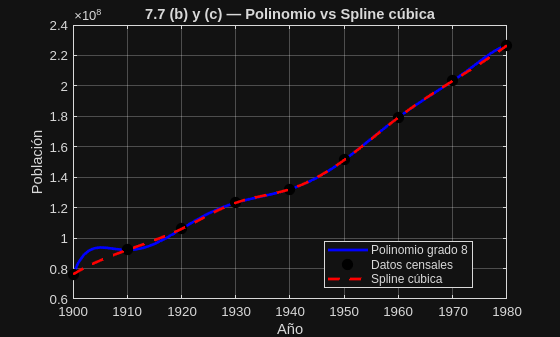

y_spline = spline(t, y, t_anual);

figure(13);
plot(t_anual, y_spline, 'r--', 'LineWidth', 2, 'DisplayName', 'Spline cúbica')
legend('Location', 'best')
title('7.7 (b) y (c) — Polinomio vs Spline cúbica')

**7.7** *(d)* Extrapolación a 1990 con polinomio y spline

y_real_1990 = 248709873;

% Extrapolación polinomio
t_1990_transf = (1990 - 1940) / 40;
y_poly_1990   = horner_base4(c, t_1990_transf);

% Extrapolación spline
y_spline_1990 = spline(t, y, 1990);

fprintf('Extrapolación a 1990:\n')

Extrapolación a 1990:


fprintf('  Valor real censo 1990    : %15.0f\n', y_real_1990)

  Valor real censo 1990    :       248709873


fprintf('  Polinomio grado 8        : %15.0f\n', y_poly_1990)

  Polinomio grado 8        :        82749141


fprintf('  Spline cúbica            : %15.0f\n', y_spline_1990)

  Spline cúbica            :       256915297


fprintf('\nErrores absolutos:\n')


Errores absolutos:


fprintf('  Error polinomio          : %15.0f\n', abs(y_poly_1990  - y_real_1990))

  Error polinomio          :       165960732


fprintf('  Error spline             : %15.0f\n', abs(y_spline_1990 - y_real_1990))

  Error spline             :         8205424


fprintf('\nErrores relativos:\n')


Errores relativos:


fprintf('  Error relativo polinomio : %.4f%%\n', abs(y_poly_1990  - y_real_1990)/y_real_1990*100)

  Error relativo polinomio : 66.7286%


fprintf('  Error relativo spline    : %.4f%%\n', abs(y_spline_1990 - y_real_1990)/y_real_1990*100)

  Error relativo spline    : 3.2992%


La extrapolación fuera del rango de datos es siempre riesgosa. El polinomio de grado alto tiende a oscilar bruscamente fuera del intervalo de interpolación. La spline extrapola usando solo el último subintervalo [1970, 1980], lo que la hace más conservadora y generalmente más cercana al valor real.

**7.7** *(e)* Interpolante de Lagrange y comparación de tiempos de ejecución

function p = lagrange_interp(t, y, x)
% Evalúa el interpolante de Lagrange en el punto x
    n = length(t);
    p = 0;
    for i = 1:n
        L = 1;
        for j = 1:n
            if j ~= i
                L = L * (x - t(j)) / (t(i) - t(j));
            end
        end
        p = p + y(i) * L;
    end
end

% Evaluación con Lagrange
y_lagrange = zeros(size(t_anual));
for k = 1:length(t_anual)
    y_lagrange(k) = lagrange_interp(t, y, t_anual(k));
end

% Comparación de tiempos
n_rep = 500;

t0 = tic;
for r = 1:n_rep
    for k = 1:length(t_anual)
        horner_base4(c, t_anual_transf(k));
    end
end
tiempo_horner = toc(t0) / n_rep;

t0 = tic;
for r = 1:n_rep
    spline(t, y, t_anual);
end
tiempo_spline = toc(t0) / n_rep;

t0 = tic;
for r = 1:n_rep
    for k = 1:length(t_anual)
        lagrange_interp(t, y, t_anual(k));
    end
end
tiempo_lagrange = toc(t0) / n_rep;

fprintf('Tiempos promedio (%d repeticiones):\n', n_rep)

Tiempos promedio (500 repeticiones):


fprintf('  Horner   : %.6f s\n', tiempo_horner)

  Horner   : 0.000056 s


fprintf('  Spline   : %.6f s\n', tiempo_spline)

  Spline   : 0.000229 s


fprintf('  Lagrange : %.6f s\n', tiempo_lagrange)

  Lagrange : 0.000068 s


fprintf('\nRatios respecto a Horner:\n')


Ratios respecto a Horner:


fprintf('  Spline   / Horner : %.2f\n', tiempo_spline   / tiempo_horner)

  Spline   / Horner : 4.11


fprintf('  Lagrange / Horner : %.2f\n', tiempo_lagrange / tiempo_horner)

  Lagrange / Horner : 1.21


Lagrange es el más lento porque para cada punto de evaluación recorre todos los nodos dos veces (bucle doble). Horner es el más rápido porque evalúa en O(n) operaciones sin productos redundantes. La spline tiene costo intermedio ya que localiza el subintervalo y evalúa un polinomio cúbico local.

**7.7** *(f)* Forma de Newton del polinomio interpolante y agregado del punto 1990

% Coeficientes de Newton para los 9 puntos originales
c_newton = newton_coeficientes(t, y);

fprintf('Coeficientes de Newton (grado 8):\n')

Coeficientes de Newton (grado 8):


for k = 1:length(c_newton)
    fprintf('  c(%d) = %15.6e\n', k, c_newton(k))
end

  c(1) =    7.621217e+07
  c(2) =    1.601633e+06
  c(3) =   -1.111643e+04
  c(4) =    9.352222e+02
  c(5) =   -7.174384e+01
  c(6) =    3.937011e+00
  c(7) =   -1.347935e-01
  c(8) =    3.078344e-03
  c(9) =   -4.809269e-05


Agregar el punto 1990 sin recalcular desde cero

t_1990 = 1990;
y_1990 = 248709873;

[c_newton9, t_newton9] = newton_agregar_punto(c_newton, t, t_1990, y_1990);

fprintf('Nuevo coeficiente agregado (grado 9):\n')

Nuevo coeficiente agregado (grado 9):


fprintf('  c(10) = %15.6e\n', c_newton9(end))

  c(10) =    4.573433e-07


Graficar ambos polinomios de Newton en [1900, 1990]

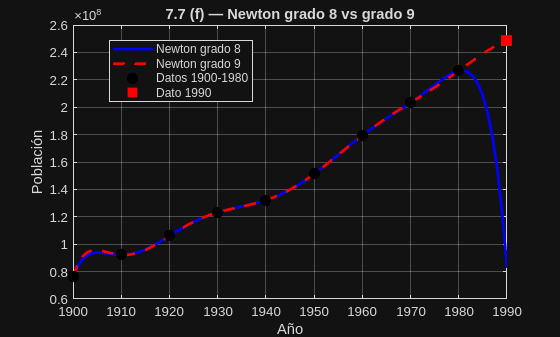

t_rango = 1900:1:1990;

y_newton8 = zeros(size(t_rango));
y_newton9 = zeros(size(t_rango));

for k = 1:length(t_rango)
    y_newton8(k) = horner_newton(c_newton,  t,        t_rango(k));
    y_newton9(k) = horner_newton(c_newton9, t_newton9, t_rango(k));
end

figure(14); clf;
plot(t_rango, y_newton8, 'b-',  'LineWidth', 2, 'DisplayName', 'Newton grado 8')
hold on
plot(t_rango, y_newton9, 'r--', 'LineWidth', 2, 'DisplayName', 'Newton grado 9')
plot(t, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Datos 1900-1980')
plot(t_1990, y_1990, 'rs', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'Dato 1990')
xlabel('Año'); ylabel('Población')
title('7.7 (f) — Newton grado 8 vs grado 9')
legend('Location', 'best'); grid on

El polinomio de grado 9 pasa exactamente por el punto de 1990 al haberlo agregado como nodo. El método de Newton permite agregar el nuevo punto calculando solo un coeficiente adicional sin rehacer todo el sistema. Fuera de los nodos ambos polinomios pueden diferir, especialmente cerca de los extremos donde los polinomios de grado alto tienden a oscilar.

**7.7** *(g)* Redondear datos al millón más cercano y comparar coeficientes

% Redondear al millón más cercano
y_redondeado = round(y / 1e6) * 1e6;

fprintf('Datos originales vs redondeados:\n')

Datos originales vs redondeados:


fprintf('  %-6s  %-15s  %-15s  %-12s\n', 'Año', 'Original', 'Redondeado', 'Diferencia')

  Año     Original         Redondeado       Diferencia  


for k = 1:length(t)
    fprintf('  %-6d  %-15.0f  %-15.0f  %-12.0f\n', ...
        t(k), y(k), y_redondeado(k), y(k) - y_redondeado(k))
end

  1900    76212168         76000000         212168      
  1910    92228496         92000000         228496      
  1920    106021537        106000000        21537       
  1930    123202624        123000000        202624      
  1940    132164569        132000000        164569      
  1950    151325798        151000000        325798      
  1960    179323175        179000000        323175      
  1970    203302031        203000000        302031      
  1980    226542199        227000000        -457801     


% Resolver con base 4 y datos redondeados
c_redondeado = V4 \ y_redondeado';

fprintf('\nComparación de coeficientes (Base 4):\n')


Comparación de coeficientes (Base 4):


fprintf('  %-6s  %-20s  %-20s  %-12s\n', 'Coef.', 'Original', 'Redondeado', 'Diferencia')

  Coef.   Original              Redondeado            Diferencia  


for k = 1:length(c)
    fprintf('  c(%-2d)   %-20.6e  %-20.6e  %-12.6e\n', ...
        k, c(k), c_redondeado(k), abs(c(k) - c_redondeado(k)))
end

  c(1 )   1.321646e+08          1.320000e+08          1.645690e+05
  c(2 )   4.613077e+07          4.595714e+07          1.736227e+05
  c(3 )   1.027163e+08          1.001413e+08          2.575045e+06
  c(4 )   1.825271e+08          1.811111e+08          1.416019e+06
  c(5 )   -3.746147e+08         -3.567556e+08         1.785916e+07
  c(6 )   -3.426685e+08         -3.384889e+08         4.179567e+06
  c(7 )   6.062912e+08          5.703111e+08          3.598014e+07
  c(8 )   1.891756e+08          1.869206e+08          2.254941e+06
  c(9 )   -3.151802e+08         -2.941968e+08         2.098341e+07


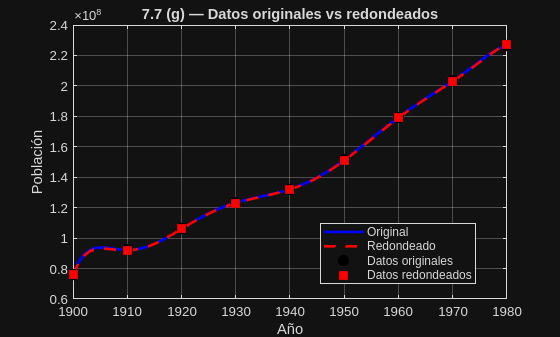

% Evaluación y gráfica comparativa
y_horner_red = zeros(size(t_anual));
for k = 1:length(t_anual)
    y_horner_red(k) = horner_base4(c_redondeado, t_anual_transf(k));
end

figure(15); clf;
plot(t_anual, y_horner,     'b-',  'LineWidth', 2, 'DisplayName', 'Original')
hold on
plot(t_anual, y_horner_red, 'r--', 'LineWidth', 2, 'DisplayName', 'Redondeado')
plot(t, y,            'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Datos originales')
plot(t, y_redondeado, 'rs', 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'DisplayName', 'Datos redondeados')
xlabel('Año'); ylabel('Población')
title('7.7 (g) — Datos originales vs redondeados')
legend('Location', 'best'); grid on

Aunque el redondeo al millón parece pequeño relativamente (menos del 1%), los coeficientes del polinomio pueden cambiar significativamente. La matriz de Vandermonde amplifica las perturbaciones en los datos al calcular los coeficientes. Este fenómeno ilustra que errores de redondeo aparentemente pequeños en los datos pueden producir coeficientes muy distintos, aunque el polinomio resultante se vea visualmente similar.

# `Métodos Numéricos con Matlab. John H Mathews`

### `Capítulo 7. Integración Numérica.`

`═══════════════════════════════════════════════════════════════`

`SEGUNDA PARTE — Integración Numérica`

`═══════════════════════════════════════════════════════════════`

`1. Integración numérica sobre [a,b] = [0,1]`

`Fórmulas de cuadratura:`

`(4) Trapecio:       h/2 * (f0 + f1)                          h = 1`

`(5) Simpson:        h/3 * (f0 + 4f1 + f2)                    h = 1/2`

`(6) Simpson 3/8:    3h/8 * (f0 + 3f1 + 3f2 + f3)             h = 1/3`

`(7) Boole:          2h/45 * (7f0 + 32f1 + 12f2 + 32f3 + 7f4) h = 1/4`

`Funciones:`

`  (a) f(x) = sin(pi*x)            exacto = 2/pi`

`  (b) f(x) = 1 + exp(-x)*cos(4x)  exacto = (18e - cos(4) + 4*sin(4))/(17e)`

`  (c) f(x) = sin(sqrt(x))         exacto = 2*(sin(1) - cos(1))`

% Funciones y valores exactos
fa = @(x) sin(pi*x);
fb = @(x) 1 + exp(-x).*cos(4*x);
fc = @(x) sin(sqrt(x));

exact_a = 2/pi;
exact_b = (18*exp(1) - cos(4) + 4*sin(4)) / (17*exp(1));
exact_c = 2*(sin(1) - cos(1));

fprintf('Valores exactos:\n')

Valores exactos:


fprintf('  (a) %.11f\n', exact_a)

  (a) 0.63661977237


fprintf('  (b) %.11f\n', exact_b)

  (b) 1.00745963140


fprintf('  (c) %.11f\n', exact_c)

  (c) 0.60233735788


**1** *(4)* — Regla del Trapecio,  h = 1

h = 1;
x = [0, 1];

trap_a = (h/2)*(fa(x(1)) + fa(x(2)));
trap_b = (h/2)*(fb(x(1)) + fb(x(2)));
trap_c = (h/2)*(fc(x(1)) + fc(x(2)));

fprintf('Trapecio (h=1):\n')

Trapecio (h=1):


fprintf('  (a) aprox=%.11f  error=%.4e\n', trap_a, abs(trap_a - exact_a))

  (a) aprox=0.00000000000  error=6.3662e-01


fprintf('  (b) aprox=%.11f  error=%.4e\n', trap_b, abs(trap_b - exact_b))

  (b) aprox=1.37976897502  error=3.7231e-01


fprintf('  (c) aprox=%.11f  error=%.4e\n', trap_c, abs(trap_c - exact_c))

  (c) aprox=0.42073549240  error=1.8160e-01


**1** *(5)* — Regla de Simpson,  h = 1/2

h = 1/2;
x = [0, 1/2, 1];

simp_a = (h/3)*(fa(x(1)) + 4*fa(x(2)) + fa(x(3)));
simp_b = (h/3)*(fb(x(1)) + 4*fb(x(2)) + fb(x(3)));
simp_c = (h/3)*(fc(x(1)) + 4*fc(x(2)) + fc(x(3)));

fprintf('Simpson (h=1/2):\n')

Simpson (h=1/2):


fprintf('  (a) aprox=%.11f  error=%.4e\n', simp_a, abs(simp_a - exact_a))

  (a) aprox=0.66666666667  error=3.0047e-02


fprintf('  (b) aprox=%.11f  error=%.4e\n', simp_b, abs(simp_b - exact_b))

  (b) aprox=0.95831911480  error=4.9141e-02


fprintf('  (c) aprox=%.11f  error=%.4e\n', simp_c, abs(simp_c - exact_c))

  (c) aprox=0.57333645685  error=2.9001e-02


**1** *(6)* — Regla 3/8 de Simpson,  h = 1/3

h = 1/3;
x = [0, 1/3, 2/3, 1];

s38_a = (3*h/8)*(fa(x(1)) + 3*fa(x(2)) + 3*fa(x(3)) + fa(x(4)));
s38_b = (3*h/8)*(fb(x(1)) + 3*fb(x(2)) + 3*fb(x(3)) + fb(x(4)));
s38_c = (3*h/8)*(fc(x(1)) + 3*fc(x(2)) + 3*fc(x(3)) + fc(x(4)));

fprintf('Simpson 3/8 (h=1/3):\n')

Simpson 3/8 (h=1/3):


fprintf('  (a) aprox=%.11f  error=%.4e\n', s38_a, abs(s38_a - exact_a))

  (a) aprox=0.64951905284  error=1.2899e-02


fprintf('  (b) aprox=%.11f  error=%.4e\n', s38_b, abs(s38_b - exact_b))

  (b) aprox=0.98692709457  error=2.0533e-02


fprintf('  (c) aprox=%.11f  error=%.4e\n', s38_c, abs(s38_c - exact_c))

  (c) aprox=0.58314269391  error=1.9195e-02


**1** *(7)* — Regla de Boole,  h = 1/4

h = 1/4;
x = [0, 1/4, 1/2, 3/4, 1];

boole_a = (2*h/45)*(7*fa(x(1)) + 32*fa(x(2)) + 12*fa(x(3)) + 32*fa(x(4)) + 7*fa(x(5)));
boole_b = (2*h/45)*(7*fb(x(1)) + 32*fb(x(2)) + 12*fb(x(3)) + 32*fb(x(4)) + 7*fb(x(5)));
boole_c = (2*h/45)*(7*fc(x(1)) + 32*fc(x(2)) + 12*fc(x(3)) + 32*fc(x(4)) + 7*fc(x(5)));

fprintf('Boole (h=1/4):\n')

Boole (h=1/4):


fprintf('  (a) aprox=%.11f  error=%.4e\n', boole_a, abs(boole_a - exact_a))

  (a) aprox=0.63616482218  error=4.5495e-04


fprintf('  (b) aprox=%.11f  error=%.4e\n', boole_b, abs(boole_b - exact_b))

  (b) aprox=1.00876275978  error=1.3031e-03


fprintf('  (c) aprox=%.11f  error=%.4e\n', boole_c, abs(boole_c - exact_c))

  (c) aprox=0.59337640893  error=8.9609e-03


**Resumen comparativo de errores**

fprintf('\n%-20s %-14s %-14s %-14s\n', 'Regla', 'Error (a)', 'Error (b)', 'Error (c)')


Regla                Error (a)      Error (b)      Error (c)     


fprintf('%s\n', repmat('-', 1, 62))

--------------------------------------------------------------


fprintf('%-20s %-14.4e %-14.4e %-14.4e\n', 'Trapecio',    abs(trap_a-exact_a),  abs(trap_b-exact_b),  abs(trap_c-exact_c))

Trapecio             6.3662e-01     3.7231e-01     1.8160e-01    


fprintf('%-20s %-14.4e %-14.4e %-14.4e\n', 'Simpson',     abs(simp_a-exact_a),  abs(simp_b-exact_b),  abs(simp_c-exact_c))

Simpson              3.0047e-02     4.9141e-02     2.9001e-02    


fprintf('%-20s %-14.4e %-14.4e %-14.4e\n', 'Simpson 3/8', abs(s38_a-exact_a),   abs(s38_b-exact_b),   abs(s38_c-exact_c))

Simpson 3/8          1.2899e-02     2.0533e-02     1.9195e-02    


fprintf('%-20s %-14.4e %-14.4e %-14.4e\n', 'Boole',       abs(boole_a-exact_a), abs(boole_b-exact_b), abs(boole_c-exact_c))

Boole                4.5495e-04     1.3031e-03     8.9609e-03    


**2.** Reglas compuestas de cuadratura sobre [0,1]

5 nodos equiespaciados con h = 1/4: x = [0, 1/4, 1/2, 3/4, 1]

Regla compuesta del Trapecio:

  h/2 * (f0 + 2f1 + 2f2 + 2f3 + f4)

Regla compuesta de Simpson:

  h/3 * (f0 + 4f1 + 2f2 + 4f3 + f4)

Regla de Boole:

  2h/45 * (7f0 + 32f1 + 12f2 + 32f3 + 7f4)

Funciones:

  (a) f(x) = sin(pi*x)            exacto = 2/pi

  (b) f(x) = 1 + exp(-x)*cos(4x)  exacto = (18e - cos(4) + 4*sin(4))/(17e)

  (c) f(x) = sin(sqrt(x))         exacto = 2*(sin(1) - cos(1))

% Nodos y funciones
h = 1/4;
x = [0, 1/4, 1/2, 3/4, 1];

% Reusar funciones y exactos del ejercicio 1
f_a = fa(x);
f_b = fb(x);
f_c = fc(x);

% Trapecio compuesto
trap_a = (h/2)*(f_a(1) + 2*f_a(2) + 2*f_a(3) + 2*f_a(4) + f_a(5));
trap_b = (h/2)*(f_b(1) + 2*f_b(2) + 2*f_b(3) + 2*f_b(4) + f_b(5));
trap_c = (h/2)*(f_c(1) + 2*f_c(2) + 2*f_c(3) + 2*f_c(4) + f_c(5));

% Simpson compuesto
simp_a = (h/3)*(f_a(1) + 4*f_a(2) + 2*f_a(3) + 4*f_a(4) + f_a(5));
simp_b = (h/3)*(f_b(1) + 4*f_b(2) + 2*f_b(3) + 4*f_b(4) + f_b(5));
simp_c = (h/3)*(f_c(1) + 4*f_c(2) + 2*f_c(3) + 4*f_c(4) + f_c(5));

% Boole
boole2_a = (2*h/45)*(7*f_a(1) + 32*f_a(2) + 12*f_a(3) + 32*f_a(4) + 7*f_a(5));
boole2_b = (2*h/45)*(7*f_b(1) + 32*f_b(2) + 12*f_b(3) + 32*f_b(4) + 7*f_b(5));
boole2_c = (2*h/45)*(7*f_c(1) + 32*f_c(2) + 12*f_c(3) + 32*f_c(4) + 7*f_c(5));

fprintf('Trapecio compuesto (h=1/4):\n')

Trapecio compuesto (h=1/4):


fprintf('  (a) aprox=%.11f  error=%.4e\n', trap_a, abs(trap_a - exact_a))

  (a) aprox=0.60355339059  error=3.3066e-02


fprintf('  (b) aprox=%.11f  error=%.4e\n', trap_b, abs(trap_b - exact_b))

  (b) aprox=1.02012791894  error=1.2668e-02


fprintf('  (c) aprox=%.11f  error=%.4e\n', trap_c, abs(trap_c - exact_c))

  (c) aprox=0.57788948788  error=2.4448e-02



fprintf('\nSimpson compuesto (h=1/4):\n')


Simpson compuesto (h=1/4):


fprintf('  (a) aprox=%.11f  error=%.4e\n', simp_a, abs(simp_a - exact_a))

  (a) aprox=0.63807118746  error=1.4514e-03


fprintf('  (b) aprox=%.11f  error=%.4e\n', simp_b, abs(simp_b - exact_b))

  (b) aprox=1.00561003197  error=1.8496e-03


fprintf('  (c) aprox=%.11f  error=%.4e\n', simp_c, abs(simp_c - exact_c))

  (c) aprox=0.59212391192  error=1.0213e-02



fprintf('\nBoole (h=1/4):\n')


Boole (h=1/4):


fprintf('  (a) aprox=%.11f  error=%.4e\n', boole2_a, abs(boole2_a - exact_a))

  (a) aprox=0.63616482218  error=4.5495e-04


fprintf('  (b) aprox=%.11f  error=%.4e\n', boole2_b, abs(boole2_b - exact_b))

  (b) aprox=1.00876275978  error=1.3031e-03


fprintf('  (c) aprox=%.11f  error=%.4e\n', boole2_c, abs(boole2_c - exact_c))

  (c) aprox=0.59337640893  error=8.9609e-03


Resumen comparativo de errores — Ejercicio 2

fprintf('\n%-22s %-14s %-14s %-14s\n', 'Regla', 'Error (a)', 'Error (b)', 'Error (c)')


Regla                  Error (a)      Error (b)      Error (c)     


fprintf('%s\n', repmat('-', 1, 64))

----------------------------------------------------------------


fprintf('%-22s %-14.4e %-14.4e %-14.4e\n', 'Trapecio compuesto',  abs(trap_a-exact_a),   abs(trap_b-exact_b),   abs(trap_c-exact_c))

Trapecio compuesto     3.3066e-02     1.2668e-02     2.4448e-02    


fprintf('%-22s %-14.4e %-14.4e %-14.4e\n', 'Simpson compuesto',   abs(simp_a-exact_a),   abs(simp_b-exact_b),   abs(simp_c-exact_c))

Simpson compuesto      1.4514e-03     1.8496e-03     1.0213e-02    


fprintf('%-22s %-14.4e %-14.4e %-14.4e\n', 'Boole',               abs(boole2_a-exact_a), abs(boole2_b-exact_b), abs(boole2_c-exact_c))

Boole                  4.5495e-04     1.3031e-03     8.9609e-03    


- ***3, 5, 6, 7, 8, 9, 10     % Los escribi en libreta***